## Running MidLineFrontal Theta Neurofeedback with Visual Stimulus

In a typical session, you will call the *nfblab_process* with the *runmode* option set to *baseline* to acquire a baseline of about 1 minute. This will allow Neurofeedbacklab to find bad channels, set up the Artifact Subspace Reconstruction filer, run ICA and find bad components. After the baseline run, you run one or more trial runs (*runmode* option set to *trial*)

See *>>nfblab_process('help', true)* for help

Note: NS crashes when connecting via EGI app starts

Possible Protocol: Check Impedance, Exit NS, Start Program, Check Impedance

How to set up multiple trials and BCILab/exec file?

Run Without Baseline

## Run Single Trial and Save Result

With *nfblab_muse_pscychotoolbox.m*

### Offline Test

Looking up software version (commit hash)
Could not look up software version; Loading software version from file.
**********************
**********************
** NEUROFEEDBACKLAB **
**********************
**********************

Version: fatal: n (git commit)

Type "help nfblab_process" for basic parameter help
Type "nfblab_process('help', true)" for more advanced parameter help
Refer to online documentation and protocols for more information.

HPF has cutoff of 1.0 Hz, transition bandwidth of 0.5 Hz and its order is 3.0
**********************
* session parameters *
**********************
    runmode                  'trial'
    warnsrate                0
    fileNameAsr              'data_nfblab_2023-10-10_16-42_asr_filter.mat'
    fileNameOut              'data_nfblab_2023-10-10_16-42.mat'
    fileNameRaw              'data_nfblab_2023-10-10_16-42_raw.set'
 

Feedback "Ready" sent to client (if any)
Decoding option runmode: trial
**********************
* session parameters *
**********************
    runmode                  'trial'
    warnsrate                0
    fileNameAsr              'data_nfblab_2023-10-10_16-42_asr_filter.mat'
    fileNameOut              'data_nfblab_2023-10-10_16-42.mat'
    fileNameRaw              'data_nfblab_2023-10-10_16-42_raw.set'
    TCPIP                    0
    TCPport                  9789
    pauseSecond              0
    baselineSessionDuration  954
    sessionDuration          954
    help                     0
    checkglobalmsg           
********************
* input parameters *
********************
    streamFile               File or data provided as input
    lsltype                  'EEG'
    lslname                  
    chans                    [1:32] 
 

Starting new session...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback {"thetaChan1":40.296185237110294,"threshold":"","value":40.296185237110294,"statechange":false,"feedback":0.55} sent to client (if any)
Feedback {"thetaChan1":38.37256354461983,"threshold":"","value":38.37256354461983,"statechange":false,"feedback":0.60000000000000009} sent to client (if any)
Feedback {"thetaChan1":38.275415043467291,"threshold":"","value":38.275415043467291,"statechange":false,"feedback":0.65000000000000013} sent to client (if any)
Feedback {"thetaChan1":39.845695910069608,"threshold":"","value":39.845695910069608,"statechange":false,"feedback":0.70000000000000018} sent to client (if any)
Feedback {"thetaChan1":42.839180555233163,"threshold":"","value":42.839180555233163,"statechange":false,"feedback":0.7500000

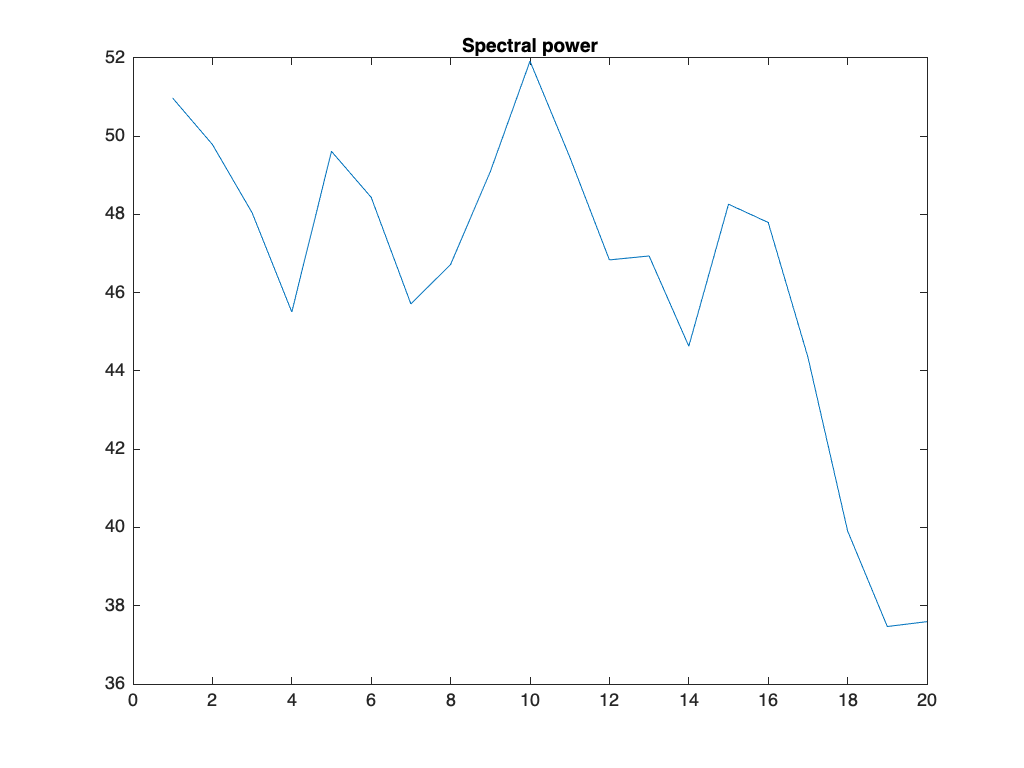

Feedback {"thetaChan1":37.593893511153922,"threshold":"","value":37.593893511153922,"statechange":false,"feedback":0.45869757532147709} sent to client (if any)
Feedback "Streaming" sent to client (if any)
Ending session...
Saving file data_nfblab_2023-10-10_16-42.mat
Feedback "paused" sent to client (if any)
Quitting...


% % Run nfblab for any headset
% % --------------------
addpath(fullfile(pwd, '..','..'));

nChan = 32; % number of channels
sRate = 128; % sampling rate

options = { ...
    'streamFile'             'eeglab_data.set' ...
    'chans'                  [1:nChan] ...
    'chanmask'               eye(nChan) ...
    'srate'                  sRate ...
    'windowSize'             sRate ...
    'simplePlot'             true ...
    'runmode'               'trial' ...
    'pauseSecond'            0 ...
    'badchanFlag'            false ...
    'icaFlag'                false ...
    'asrFlag'                false ...
    'freqrange'              { [4 8] [8 12] [8 10] [10 12] [18 22] [4 10] [12 15] [20 30] } ... 
    'feedbackMode'           'dynrange' ...
    'funcinit'               'nfblab_feedback_psychootoolbox_init' ...
    'funcfeedback'           'nfblab_feedback_psychootoolbox_process' ...
    'funcend'                'nfblab_feedback_psychootoolbox_end' ...
    };

nfblab_process(options{:});

## Run Baseline

With *nfblab_process.m *with the *runmode* option set to *baseline* to acquire a baseline of about 1 minute/

    nfblab_process('runmode', 'baseline', 'fileNameAsr', asrFileName)

### Offline Test:

% Run nfblab for any headset
% --------------------
addpath(fullfile(pwd, '..','..'));

nChan = 32; % number of channels
sRate = 128; % sampling rate

% The program will search for an LSL stream of type EEG
% It will then control a curve (simpleplot) based on the theta
% power of the first channel (default value for parameter 'freqprocess').
% See nfblab_setfield for all available options.

% tested with Psychtoolbox-3-3.0.19.0

%from multisession
subjectName = input('Initials of the subject:','s');
subjectName = lower(subjectName);
session = input('Session Day: ','s');

c = clock;
timeTag2 = [sprintf('%04.0f',c(1)) '-' sprintf('%02.0f',c(2)) '-' sprintf('%02.0f',c(3))];
timeTag = [timeTag2 '-' sprintf('%02.0f',c(4)) 'h' sprintf('%02.0f',c(5))];
asrFileName = fullfile(subjectName, ['baseline_' int2str(session) '_' timeTag2 '_ASR_state.mat' ]);
fprintf('ASR file name is: %s\n', asrFileName)

ASR file name is: ds/baseline_49_2023-10-10_ASR_state.mat


%%%%%%%%%%%%

%%req: folder with initials
if isempty(dir(subjectName))% subject folder does not exist
    display("/nSubject folder does not exist. Making folder.../n")
    mkdir(subjectName)
end

    "/nSubject folder does not exist. Making folder.../n"




options = { ...
    'streamFile'             'eeglab_data.set' ...
    'chans'                  [1:nChan] ...
    'chanmask'               eye(nChan) ...
    'srate'                  sRate ...
    'windowSize'             sRate ...
    'runmode'                'baseline' ...
    'sessionDuration'        300 ...
    'simplePlot'             true ...
    'feedbackMode'           'dynrange' ...
    'fileNameAsr'            asrFileName ...
    'pauseSecond'            0 ...
    'badchanFlag'            false ...
    'icaFlag'                false ...
    'asrFlag'                true ...
    };

nfblab_process(options{:}); 

Looking up software version (commit hash)
Could not look up software version; Loading software version from file.
**********************
**********************
** NEUROFEEDBACKLAB **
**********************
**********************

Version: fatal: n (git commit)

Type "help nfblab_process" for basic parameter help
Type "nfblab_process('help', true)" for more advanced parameter help
Refer to online documentation and protocols for more information.

Note: default ASR instroduces a delay - in our experience 1/4 second)
HPF has cutoff of 1.0 Hz, transition bandwidth of 0.5 Hz and its order is 3.0
**********************
* session parameters *
**********************
    runmode                  'baseline'
    warnsrate                0
    fileNameAsr              'ds/baseline_49_2023-10-10_ASR_state.mat'
    fileNameOut              'data_nfblab_2023-10-10_17-18.mat'
    fileNameRaw              'data_nfblab_2023-10-10_17-18_raw.set'

Feedback "Ready" sent to client (if any)
Decoding option runmode: baseline
Note: default ASR instroduces a delay - in our experience 1/4 second)
**********************
* session parameters *
**********************
    runmode                  'baseline'
    warnsrate                0
    fileNameAsr              'ds/baseline_49_2023-10-10_ASR_state.mat'
    fileNameOut              'data_nfblab_2023-10-10_17-18.mat'
    fileNameRaw              'data_nfblab_2023-10-10_17-18_raw.set'
    TCPIP                    0
    TCPport                  9789
    pauseSecond              0
    baselineSessionDuration  954
    sessionDuration          954
    help                     0
    checkglobalmsg           
********************
* input parameters *
********************
    streamFile               File or data provided as input
    lsltype                  'E

Starting new session...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback {"thetaChan1":39.607483382797383,"threshold":"","value":39.607483382797383,"statechange":false,"feedback":0.55} sent to client (if any)
Feedback {"thetaChan1":39.67728507780626,"threshold":"","value":39.67728507780626,"statechange":false,"feedback":0.60000000000000009} sent to client (if any)
Feedback {"thetaChan1":38.94343245270187,"threshold":"","value":38.94343245270187,"statechange":false,"feedback":0.65000000000000013} sent to client (if any)
Feedback {"thetaChan1":38.581087292780047,"threshold":"","value":38.581087292780047,"statechange":false,"feedback":0.70000000000000018} sent to client (if any)
Feedback {"thetaChan1":38.84601123078906,"threshold":"","value":38.84601123078906,"statechange":false,"feedback":0.75000000000

%'streamFile'             fullfile('..', 'basic_offline', 'eeglab_data.set') ...

## Run Single Trial and Save Result

With *nfblab_muse_pscychotoolbox.m*

### Offline Test

% % Run nfblab for any headset
% % --------------------
% Run nfblab for any headset
% --------------------
addpath(fullfile(pwd, '..','..'));

nChan = 32; % number of channels
sRate = 128; % sampling rate

% The program will search for an LSL stream of type EEG
% It will then control a curve (simpleplot) based on the theta
% power of the first channel (default value for parameter 'freqprocess').
% See nfblab_setfield for all available options.

Trial = 1;
folderName = fprintf("subjectName/%d",Trial)

subjectName/1

folderName = 13

%new directory per trial
% cd(folderName)

options = { ...
    'streamFile'             'eeglab_data.set' ...
    'chans'                  [1:nChan] ...
    'chanmask'               eye(nChan) ...
    'srate'                  sRate ...
    'windowSize'             sRate ...
    'runmode'               'trial' ...
    'pauseSecond'            0 ...
    'badchanFlag'            false ...
    'icaFlag'                false ...
    'asrFlag'                false ...
    'sessionDuration'        3600 ...
    'freqrange'              { [4 8] [8 12] [8 10] [10 12] [18 22] [4 10] [12 15] [20 30] } ...
    'feedbackMode'           'dynrange' ...
    'funcinit'               'nfblab_feedback_psychootoolbox_init' ...
    'funcfeedback'           'nfblab_feedback_psychootoolbox_process' ...
    'funcend'                'nfblab_feedback_psychootoolbox_end' ...
    };

nfblab_process(options{:});

Looking up software version (commit hash)
Could not look up software version; Loading software version from file.
**********************
**********************
** NEUROFEEDBACKLAB **
**********************
**********************

Version: fatal: n (git commit)

Type "help nfblab_process" for basic parameter help
Type "nfblab_process('help', true)" for more advanced parameter help
Refer to online documentation and protocols for more information.

HPF has cutoff of 1.0 Hz, transition bandwidth of 0.5 Hz and its order is 3.0
**********************
* session parameters *
**********************
    runmode                  'trial'
    warnsrate                0
    fileNameAsr              'data_nfblab_2023-10-20_15-03_asr_filter.mat'
    fileNameOut              'data_nfblab_2023-10-20_15-03.mat'
    fileNameRaw              'data_nfblab_2023-10-20_15-03_raw.set'
    TCPIP                    0
    TCPport                  9789
   

Could not execute feedback function, try running it as a script
PTB-INFO: Retina display. Enabling panel fitter for scaled Retina compatibility mode.


PTB-INFO: This is Psychtoolbox-3 for Apple macOS, under Matlab 64-Bit (Version 3.0.19 - Build date: May  1 2023).
PTB-INFO: OS support status: macOS version 13 Intel is minimally tested and supported.
PTB-INFO: Type 'PsychtoolboxVersion' for more detailed version information.
PTB-INFO: Most parts of the Psychtoolbox distribution are licensed to you under terms of the MIT License, with
PTB-INFO: some restrictions. See file 'License.txt' in the Psychtoolbox root folder for the exact licensing conditions.

PTB-INFO: For information about paid support, support memberships and other commercial services, please type
PTB-INFO: 'PsychPaidSupportAndServices'.

PTB-INFO: Installation of the PsychtoolboxKernelDrive

ans = 10

Feedback "Ready" sent to client (if any)
Decoding option runmode: trial
**********************
* session parameters *
**********************
    runmode                  'trial'
    warnsrate                0
    fileNameAsr              'data_nfblab_2023-10-20_15-03_asr_filter.mat'
    fileNameOut              'data_nfblab_2023-10-20_15-03.mat'
    fileNameRaw              'data_nfblab_2023-10-20_15-03_raw.set'
    TCPIP                    0
    TCPport                  9789
    pauseSecond              0
    baselineSessionDuration  954
    sessionDuration          954
    help                     0
    checkglobalmsg           
********************
* input parameters *
********************
    streamFile               File or data provided as input
    lsltype                  'EEG'
    lslname                  
    chans                    [1:32] 
    srate                    128
    chanlocs                 struct('labels',{'FPz','EOG1','F3','Fz','F4','EOG2','FC5','FC1','FC2','FC6

Starting new session...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback "Streaming" sent to client (if any)
Feedback {"thetaChan1":40.296185237110294,"threshold":"","value":40.296185237110294,"statechange":false,"feedback":0.55} sent to client (if any)
Feedback {"thetaChan1":38.37256354461983,"threshold":"","value":38.37256354461983,"statechange":false,"feedback":0.60000000000000009} sent to client (if any)
Feedback {"thetaChan1":38.275415043467291,"threshold":"","value":38.275415043467291,"statechange":false,"feedback":0.65000000000000013} sent to client (if any)
Feedback {"thetaChan1":39.845695910069608,"threshold":"","value":39.845695910069608,"statechange":false,"feedback":0.70000000000000018} sent to client (if any)
Feedback {"thetaChan1":42.839180555233163,"threshold":"","value":42.839180555233163,"statechange":false,"feedback":0.7500000